# Example solution

This live script illustrates how to use the Toolbox.

Initialization essentially consistes in loading into the workspace:

- A building mesh, both in its complete form (for representation) and its simplified one (which makes collision checking faster).

- The Points of Interest, separately generated from the mesh.

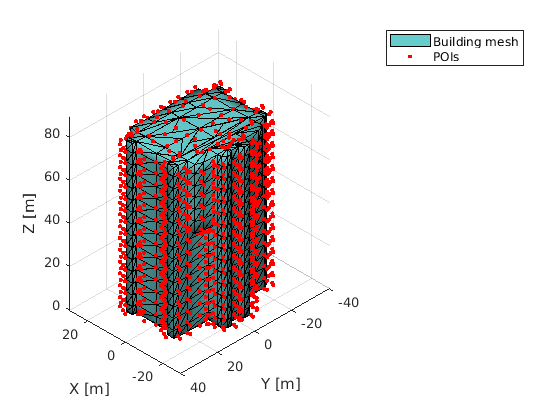

% Load Data
load buildings/UCLA/building.mat
load buildings/UCLA/mergedMesh.mat
load buildings/UCLA/points.mat

problemParameters.startingPoint = [40 40 0]; % Home point where all vehicles are supposed to start from

% Assert there are no points inside mesh
assert(max(inpolyhedron(mesh, points))== 0, "ERROR: there are points inside the building mesh");
% Draw loaded assets
figure
hold on
displayMesh(mesh)
scatter3(points(:,1),points(:,2),points(:,3), '.r')
xlim([-30 30]), ylim([-40 40]), zlim([0 90])
legend("Building mesh", "POIs")

It is then necessary to specify some problem parameters, such as the number of clusters and vehicles.

problemParameters.clusters = 10;
problemParameters.vehicles = 4;
problemParameters.vehicleCapacity = 3000; % Maximum vehicle capacity
problemParameters.optimizer = "MATLAB"; % 'MATLAB' uses intlinprog() to solve CVRP instances.
% If you have it installed, you can use 'CPLEX', which is quite faster.
problemParameters.debug = false; % Plots figures of intermediate steps, to check everything is going correctly
problemParameters.graphMinDegree = 4; % Minimum node degree in the graph for the connectivity minimization procedure (see paper)
problemParameters.verbose = true; % This signals the program to describe what it is doing
problemParameters.minMaxing = false; % Use regular or min-maxing formulation (see paper)

% Plan the trajectories. This may take some time, depending on how many
% points, clusters and vehicles there are. It also starts the parallel
% pool.
sol = planTrajectories(points, problemParameters, mesh, mergedMesh);

Now solving with 10 clusters, 4 drones
CVRP solution found, # of subtours: 4
CVRP solution found, # of subtours: 2
CVRP solution found, # of subtours: 4
CVRP solution found, # of subtours: 2
CVRP solution found, # of subtours: 2
CVRP solution found, # of subtours: 2
CVRP solution found, # of subtours: 2
CVRP solution found, # of subtours: 1


The solution has been calculated, now let's represent it. The solution object has various fields, carrying information about the solution itself.

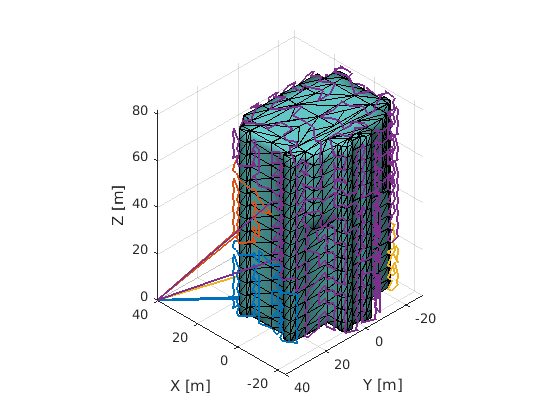

% Plot the solution and the mesh
figure
hold on
displayMesh(mesh)
for k = 1:sol.vehicles
    plot3(sol.trajectories{k}(:,1), sol.trajectories{k}(:,2), sol.trajectories{k}(:,3), "LineWidth", 1.5)
end

fprintf("A solution has been found with %d vehicles and %d clusters, spanning a total of %.1f m.\nIt took %.2f s to solve CVRP instances and %.2f s to solve TSPs.", sol.vehicles, problemParameters.clusters, sum(sol.spans), sol.times.CVRPsolution, sol.times.TSPsolution)

A solution has been found with 4 vehicles and 10 clusters, spanning a total of 4235.3 m.
It took 0.85 s to solve CVRP instances and 4.85 s to solve TSPs.

It is also possible to simulate the failure of a drone at a random point during the trajectory and replan the rest of the task:

Drone 4 failed after visiting node 8 (at edge 2), replanning
CVRP solution found, # of subtours: 3
CVRP solution found, # of subtours: 1


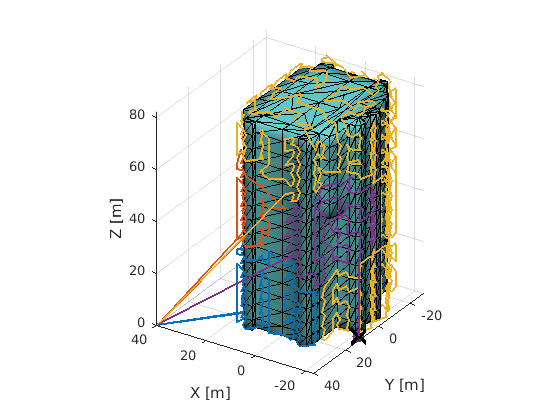

% Let's say, for example, that the drone with the longest assigned
% trajectory fails after visiting the first node completely.
[m, problemParameters.failDrone] = max(sol.spans);
problemParameters.failEdge = 2;
problemParameters.displayNewSolution = true;

newSol = failAndReplan(sol, problemParameters, mesh);

A new solution has been found with 3 vehicles and 10 clusters, spanning a total of 352.3 m.
It took 0.16 s to solve CVRP instances and 2.92 s to solve TSPs.

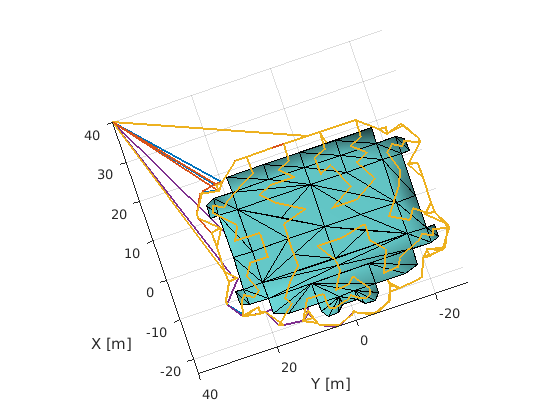

fprintf("A new solution has been found with %d vehicles and %d clusters, spanning a total of %.1f m.\nIt took %.2f s to solve CVRP instances and %.2f s to solve TSPs.", newSol.vehicles-1, problemParameters.clusters, sum(newSol.spans), newSol.times.CVRPsolution, newSol.times.TSPsolution)